Problem 7 - assume it meant program the exact algorithm 1.3, the sum of products across one matrix's rows and one matrix's columns. 

my_a = randi(10,5);
my_b = randi(10,5);
cross_prod_alg(my_a,my_b)

ans =     10    35     4    50    30
     9     7     4    45    24
    25     9    72     5    36
     6    30    32     4    72
   100    30    48     4    10


Problem 7-2 - assuming Q7 meant take the cross product of two matrixes

cross_product_simple = my_a * my_b

cross_product_simple =    150   117   163    91   256
   132   111   177    85   282
   121    81   160    53   237
    98   116   117   108   208
    56    76    90    78   172


Problem 8 -

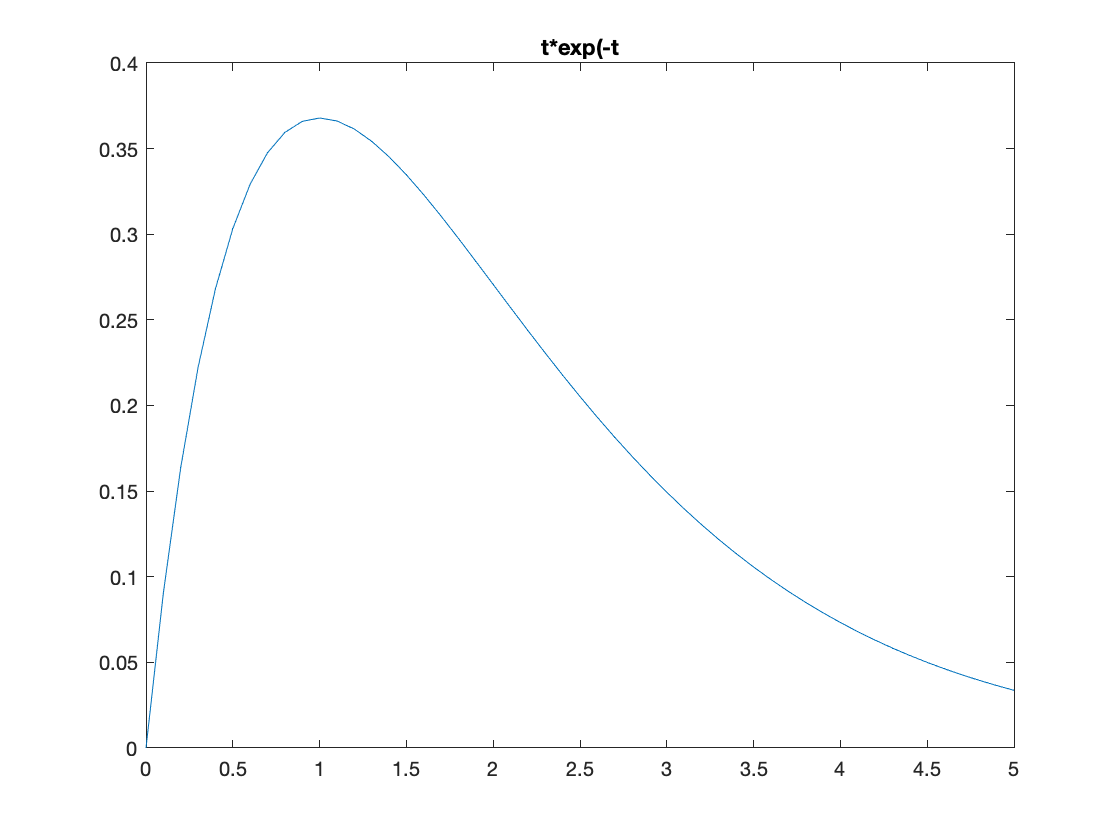

syms y t;
y = t*exp(-t);
t1 = 0:0.1:5;
y1 = subs(y,t,t1);
plot(t1,y1)
title('t*exp(-t')

problem 12 - 

[complex_product,complex_division] = cmplx(2+3i, 4-6i)

complex_product = 26

complex_division = -0.1923 + 0.4615i

problem 13

I found this question unclear. I made the following assumptions

- we're being asked to evaluate an input - we should sanitize data, throw errrors if it fails.

- we're being asked to create a function with no user input, it's called by another function. 

- I assume the proper operation of the function is to be passed a vector of length 2.

return_larger([13 -14+9j])

ans = 16.6433

Problem 15

A prime number is a natural number that has exactly two distinct natural number divisors: 1 and itself. The first two prime numbers are 1 and 2. Write a program that finds the prime numbers between 3 and 101. Tip: Use the command rem to check if the remainder of a division is zero.  

primes = [2];
for targets = 3:101
    target = floor(targets/2);
    for iter = 1:length(primes)
        if mod(target, primes(iter))==0 || mod(target, primes(iter))==1
            break;
        end
    end
    primes(end+1)=targets;
end
primes

Problem 17

syms y x; 
func1 = y==1-x*x;
func2 = y==1+x;
[sols_x, sols_y] = solve(func1, func2, x,y)

Problem 18

syms x(t) y(t);
eqn1 = diff(x,t) == -y(t);
cond1 = y(0)==3;

eqn2 = diff(y,t)==-x(t);;
cond2 = x(0) == 4;

S = dsolve(eqn1, eqn2, cond1, cond2);

f(t) = S.y;
g(t) = S.x;

fplot(f)
hold on
fplot(g)
hold off

xlim([0 5])

function definition for problem 12

function[prod, div] = cmplx(a,b)
prod = a*b;
div = a/b;
end


Function problem 13

function[larger] = return_larger(m)
if(length(m)~=2)
    error('vector must be of length 2');
end
if(isa(m(1),'char')|| isa(m(2),'char'))
    error('this function only processes numbers');
end
larger = max(abs(m(1)),abs(m(2)));
end

function problem 7

function[cross_prod] = cross_prod_alg(m_a, m_b)
% get matrix sizes
[x_a,y_a] = size(m_a);
[y_b,z_b] = size(m_b);
% check if correct size
if y_a==y_b
    cross_prod = zeros(x_a,z_b);
    % Get Row and column
    count = 1;
    while y_a >= count
        a_row = m_a(:,count);
        b_column = m_b(count, :);
        inner_count = 1;
        while length(a_row) >= inner_count
            cross_prod(count,inner_count) = a_row(inner_count)*b_column(inner_count);
            inner_count = inner_count + 1;
        end
        count = count + 1;
    end
end
end